# Traitement du signal TD1 MATLAB

## Quelques éléments de syntaxe du language MATLAB

Le nom MATLAB vient de ***Mat****rix ****Lab****oratory.*

Voici la syntaxe pour réaliser une matrice 2x4 sur matlab :

a = [1 2 3 4 ; 5 6 7 8]

a =      1     2     3     4
     5     6     7     8


Le charactère '**;**' à la fin d'une commande permet de silencier la sortie sur cette commande.

### Début de programme

En début de programe nous allons avoir tendance à utiliser les commandes suivantes :

clear; % Permet d'effacer toutes les variables de la mémoire ou du 'workspace'
close all; % Ferme toutes les fenètres des graphiques
clc; % Efface la 'Command Window'

L'indèxation de MATLAB ne démarre à 1 contrairement à beacoup de languages infomatiques.

c = [ 1  2  3  4;
      5  6  7  8;
      9 10 11 12;
     13 14 15 16]

c =      1     2     3     4
     5     6     7     8
     9    10    11    12
    13    14    15    16


% Pour extraire un élément de la matrice c, on utilise :
b = c(2,3) % La variable b contient le nombre à la deuxième ligne et 3ème colone de c

b = 7

 Maintenant nous allons extraire une matrice plus petite que c

d = c(2:3, 2:4) % Cette ligne permet d'extraire la matrice allant de la 2e à la 3e ligne et de la 2e à la 4e colonne

d =      6     7     8
    10    11    12



e = c(2,:) % Une matrice le la ligne 2

e =      5     6     7     8


f = c(:,2) % Une matrice contenant la colone 2

f =      2
     6
    10
    14


### Produit/carré de deux matrices

g = c^2 % Produit de deux matrices

g =     90   100   110   120
   202   228   254   280
   314   356   398   440
   426   484   542   600


### Produit terme à terme

h = c.^2 % Produit terme à terme

h =      1     4     9    16
    25    36    49    64
    81   100   121   144
   169   196   225   256


## Exercice Corrélation

clear;
close all;
clc;
n = 0:39;
x = sin(2*pi*n/20);

%plot(x)
%figure
%stem(x)

disp('=============================================================')

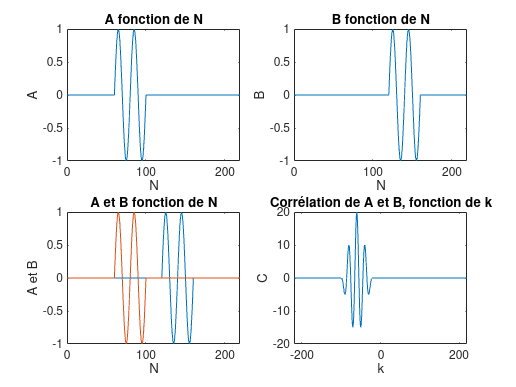


% ones(,)
A = [zeros(1,60), x, zeros(1,120)];
B = [zeros(1,120), x, zeros(1,60)];
N = 0:219;

subplot(221)
plot(N,A)
title('A fonction de N')
xlabel('N')
ylabel('A')

subplot(222)
plot(N,B)
title('B fonction de N')
xlabel('N')
ylabel('B')

subplot(223)
plot(N,B)
hold on
ylabel('A et B')
plot(N,A)
title('A et B fonction de N')
xlabel('N')


[C, k] = xcorr(A,B);

% C en fonction de k
subplot(224)
plot(k,C)
title('Corrélation de A et B, fonction de k')
xlabel('k')
ylabel('C')